# Initialize

close all;
clear variables; 
global n_plot
init_FB();

### Observation bandwidth

f_min = 200e9; % lowest frequency
f_max = 460e9; % highest frequency
nF    = 1e4; %number of frequency samples
f     = linspace(f_min,f_max,nF); % frequency  

### Filter-bank properties

Qi          = Inf;%3000; %3300;%Inf; % It can be a vector
sep         = 1/4; %0.133;%0.1625;%1/4;%1/2;%3/4;
Ql_target   = 100;
ThruLineLosses = 0; 
S           = 1; % Oversampling

f0_min      = 220e9;
f0_max      = 2*f0_min;
nFilters    = floor( 1 + log10(f0_max / f0_min) / log10(1 + 1 ./ Ql_target ./ S) );

f0          = zeros(1,nFilters);
f0(1)       = f0_min;

for filter_i=2:nFilters
   f0(filter_i) = f0(filter_i-1) + f0(filter_i-1) * 1 ./ Ql_target ./ S;
end
f0 = sort(f0,'descend');

% TL-Impedances
Z0_KID      = 54.81;
Z0_thru     = 79.04;



singleFilterPlot = nFilters;

% SET SETTINGS
Settings.singleFilterPlot = nFilters; 
Settings.Z0_thru = Z0_thru;
Settings.Z0_KID = Z0_KID;
Settings.Qi = Qi;
Settings.ThruLineLosses = ThruLineLosses;
Settings.sep = sep;
Settings.f0 = f0;
Settings.Ql_target = Ql_target;

### Loop

n_loops = 10;

for iter = 1:n_loops
    n_plot = 0;



### Variances

    %% Ql %%
    Ql_sigma = 0.1; % Variance of Ql, normalized to 1
    
    %% f0 %%
    f0_sigma = 0;%0.27;% .* Ql_target ./ 500; % Relative variance of f0 (df), normalized to 1. 
    f0_drift = 0; % linear drift of f0
    f0_offset = 0; % additive offset of f0
    
    % Lower bound on Ql_scattered, based on analysis of Deshima II by Akira
    Ql_min_thresh = -1.5 .* Ql_target .* Ql_sigma;
    
    
    
    num_elem = 4; 
    Ql_variance = zeros(num_elem,nFilters);
    f0_variance = zeros(num_elem,nFilters);
    
    interFilterVariance = true;
    
    
    if interFilterVariance
        
%         Ql_sigma = Ql_sigma ./ sqrt(2);
%         f0_sigma = f0_sigma ./ sqrt(2);
    
        for i_elem = 1:num_elem %#ok<*UNRCH> 
            
            %%%% Scattered design parameters %%%%
            Ql_variance(i_elem,:) = Ql_target .* Ql_sigma .* randn(1,nFilters);
            Ql_variance(i_elem,Ql_variance(i_elem,:) < Ql_min_thresh) = Ql_min_thresh;
            df = f0 ./ Ql_target;
            f0_variance(i_elem,:) = df .* f0_sigma .* randn(1,nFilters);
        end
    else
        
        %%%% Scattered design parameters %%%%
        Ql_variance = repmat(Ql_target .* Ql_sigma .* randn(1,nFilters),4,1);
        Ql_variance(Ql_variance < Ql_min_thresh) = Ql_min_thresh;
        df = f0 ./ Ql_target;
        f0_variance = repmat(df .* f0_sigma .* randn(1,nFilters),4,1);
    end
    
    Settings.f0_variance = f0_variance;
    Settings.Ql_variance = Ql_variance;

# Filterbanks

## Directional filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceDirectionalFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 4.382256 seconds


Section took 5.915374 seconds


Section took 5.218468 seconds


Section took 5.095316 seconds


Section took 5.060386 seconds


Section took 5.000004 seconds


Section took 5.055618 seconds


Section took 5.202548 seconds


Section took 5.089963 seconds


Section took 5.079927 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_dir(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.530766 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.88
Section took 0.552569 seconds


Section took 1.710627 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.90
Section took 0.571596 seconds


Section took 1.575901 seconds
Usable Spectral Fraction old = 1.00
Usable Spectral Fraction half mean envelope = 0.91
Section took 0.572152 seconds


Section took 1.579749 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.90
Section took 0.542167 seconds


Section took 1.574334 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.89
Section took 0.548010 seconds


Section took 1.598713 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.88
Section took 0.541276 seconds


Section took 1.558637 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.90
Section took 0.547021 seconds


Section took 1.568382 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.89
Section took 0.538368 seconds


Section took 1.585286 seconds
Usable Spectral Fraction old = 1.00
Usable Spectral Fraction half mean envelope = 0.91
Section took 0.536555 seconds


Section took 1.611137 seconds
Usable Spectral Fraction old = 1.00
Usable Spectral Fraction half mean envelope = 0.92
Section took 0.553192 seconds


    % % % showDimensions(f,f0,l_thru)

## Reflector filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceReflectorFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 2.555687 seconds


Section took 2.644382 seconds


Section took 2.952034 seconds


Section took 2.909488 seconds


Section took 2.889692 seconds


Section took 2.870574 seconds


Section took 2.864131 seconds


Section took 2.843106 seconds


Section took 2.926655 seconds


Section took 2.922367 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_refl(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.313345 seconds
Usable Spectral Fraction old = 0.96
Usable Spectral Fraction half mean envelope = 0.86
Section took 0.475669 seconds


Section took 1.315264 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.88
Section took 0.489979 seconds


Section took 1.441884 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.88
Section took 0.547287 seconds


Section took 1.438881 seconds
Usable Spectral Fraction old = 0.98
Usable Spectral Fraction half mean envelope = 0.88
Section took 0.549575 seconds


Section took 1.428583 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.90
Section took 0.586981 seconds


Section took 1.437779 seconds
Usable Spectral Fraction old = 0.97
Usable Spectral Fraction half mean envelope = 0.86
Section took 0.536188 seconds


Section took 1.430040 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.90
Section took 0.541507 seconds


Section took 1.424185 seconds
Usable Spectral Fraction old = 0.97
Usable Spectral Fraction half mean envelope = 0.86
Section took 0.542045 seconds


Section took 1.438895 seconds
Usable Spectral Fraction old = 0.98
Usable Spectral Fraction half mean envelope = 0.89
Section took 0.587666 seconds


Section took 1.404570 seconds
Usable Spectral Fraction old = 0.99
Usable Spectral Fraction half mean envelope = 0.92
Section took 0.533090 seconds


    % % % % showDimensions(f,f0,l_thru)

## Manifold filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceManifoldFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 2.062923 seconds


Section took 2.265157 seconds


Section took 2.221296 seconds


Section took 2.226176 seconds


Section took 2.169506 seconds


Section took 2.188226 seconds


Section took 2.207839 seconds


Section took 2.205776 seconds


Section took 2.240735 seconds


Section took 2.203968 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_man(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.493738 seconds
Usable Spectral Fraction old = 0.89
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.621410 seconds


Section took 1.673561 seconds
Usable Spectral Fraction old = 0.90
Usable Spectral Fraction half mean envelope = 0.76
Section took 0.592855 seconds


Section took 1.447193 seconds
Usable Spectral Fraction old = 0.90
Usable Spectral Fraction half mean envelope = 0.76
Section took 0.544677 seconds


Section took 1.415049 seconds
Usable Spectral Fraction old = 0.88
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.547383 seconds


Section took 1.538060 seconds
Usable Spectral Fraction old = 0.91
Usable Spectral Fraction half mean envelope = 0.77
Section took 0.577175 seconds


Section took 1.405637 seconds
Usable Spectral Fraction old = 0.88
Usable Spectral Fraction half mean envelope = 0.71
Section took 0.523372 seconds


Section took 1.402846 seconds
Usable Spectral Fraction old = 0.89
Usable Spectral Fraction half mean envelope = 0.76
Section took 0.534377 seconds


Section took 1.417008 seconds
Usable Spectral Fraction old = 0.89
Usable Spectral Fraction half mean envelope = 0.76
Section took 0.523159 seconds


Section took 1.452881 seconds
Usable Spectral Fraction old = 0.91
Usable Spectral Fraction half mean envelope = 0.76
Section took 0.526650 seconds


Section took 1.386823 seconds
Usable Spectral Fraction old = 0.92
Usable Spectral Fraction half mean envelope = 0.77
Section took 0.530518 seconds


    % % showDimensions(f,f0,l_thru)
    
end

## Plotting

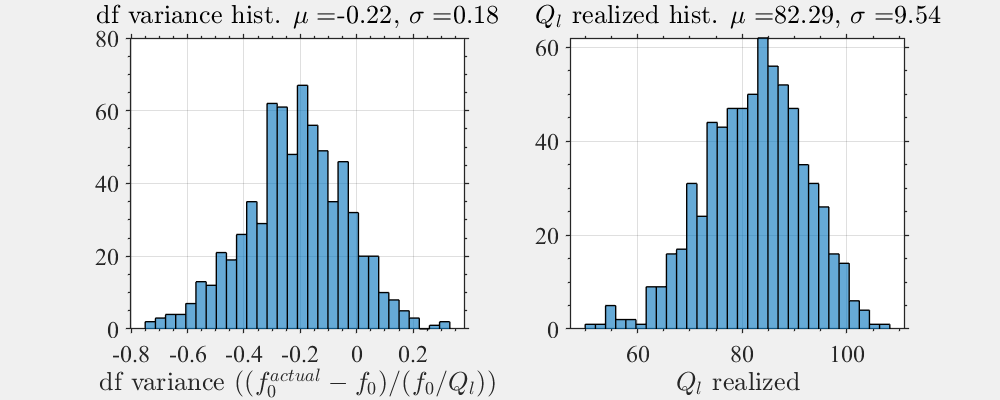

close all; 
clear functions; %#ok<CLFUNC>
n_plot = 1;
showFilterBank(f,Data_dir); 
showMetrics(f,Ql_target,Data_dir);

Stats_dir = calcStatistics(f0,Ql_target,Data_dir);
showStatistics(f,Data_dir,Stats_dir);

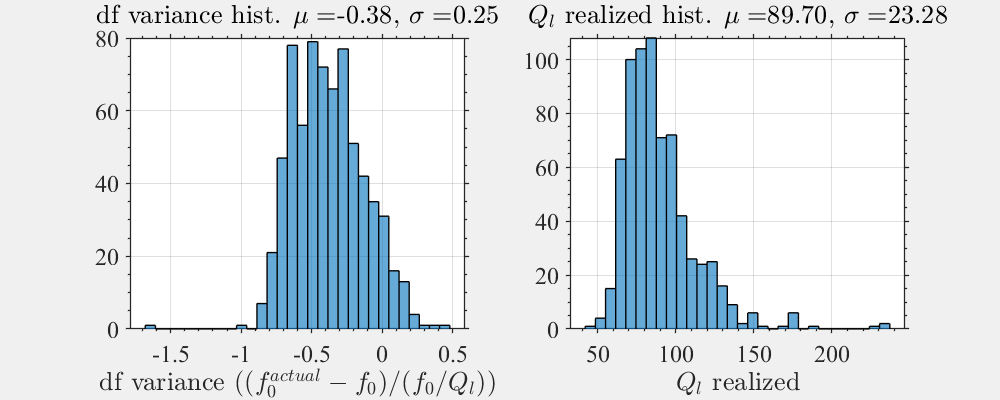


n_plot = 2;
showFilterBank(f,Data_refl);
showMetrics(f,Ql_target,Data_refl);

Stats_refl = calcStatistics(f0,Ql_target,Data_refl);
showStatistics(f,Data_refl,Stats_refl);

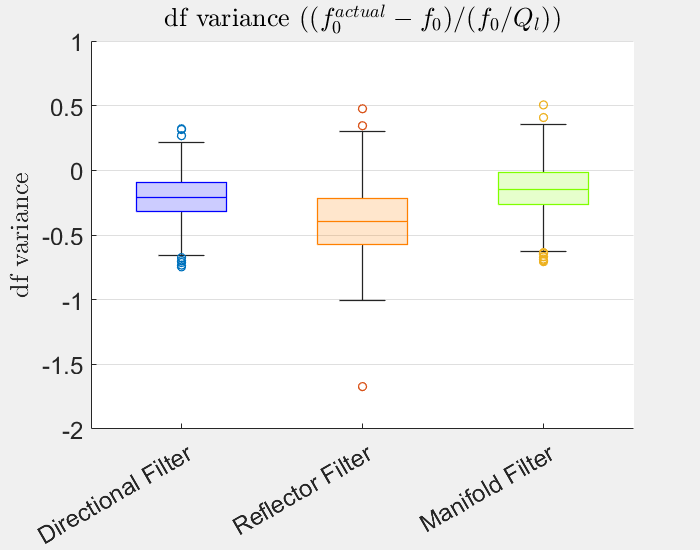

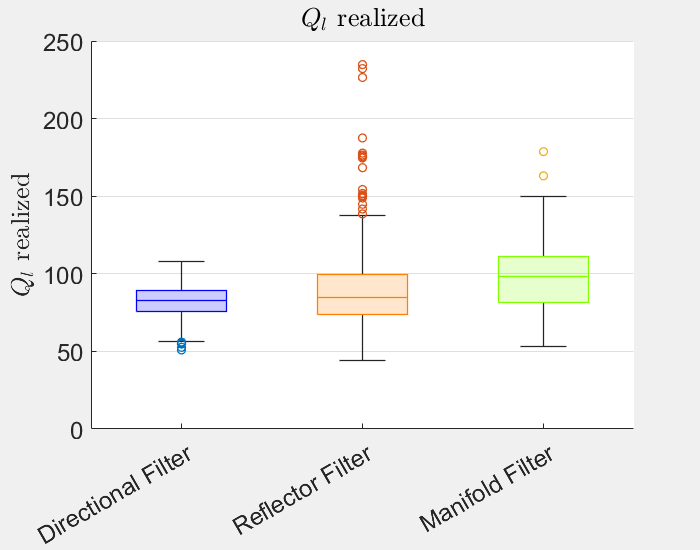

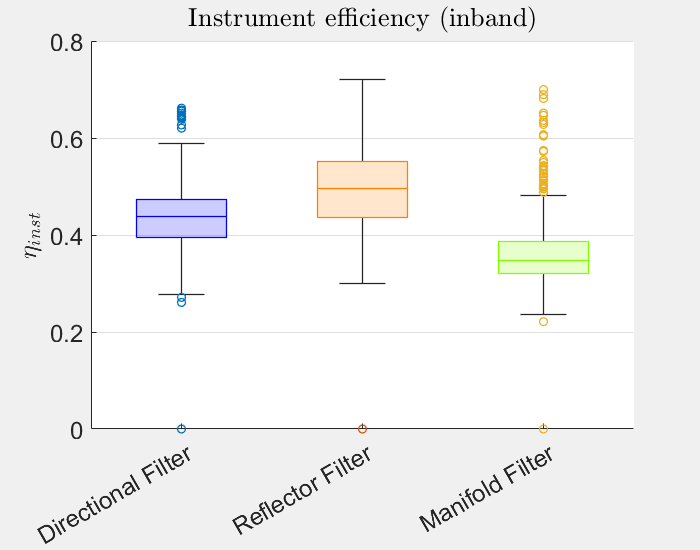

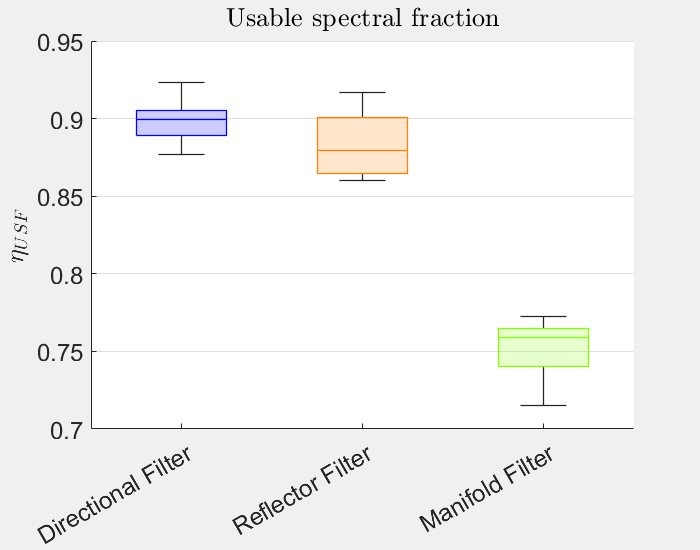

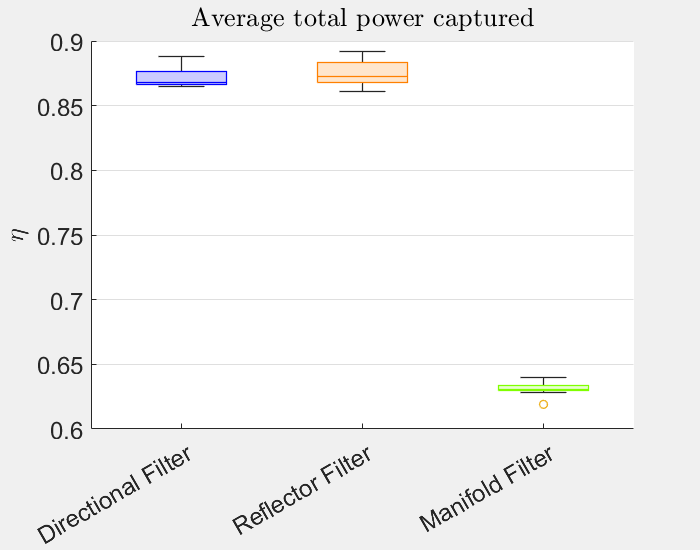

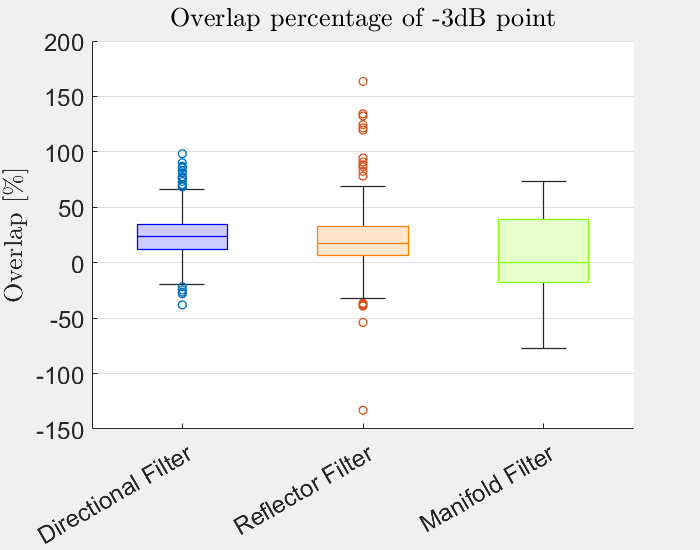

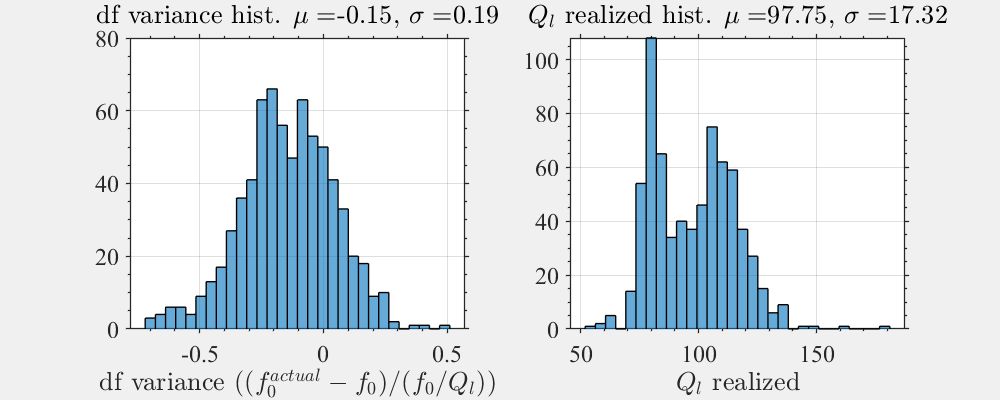



n_plot = 3;
showFilterBank(f,Data_man);
showMetrics(f,Ql_target,Data_man);

Stats_man = calcStatistics(f0,Ql_target,Data_man);
showStatistics(f,Data_man,Stats_man);

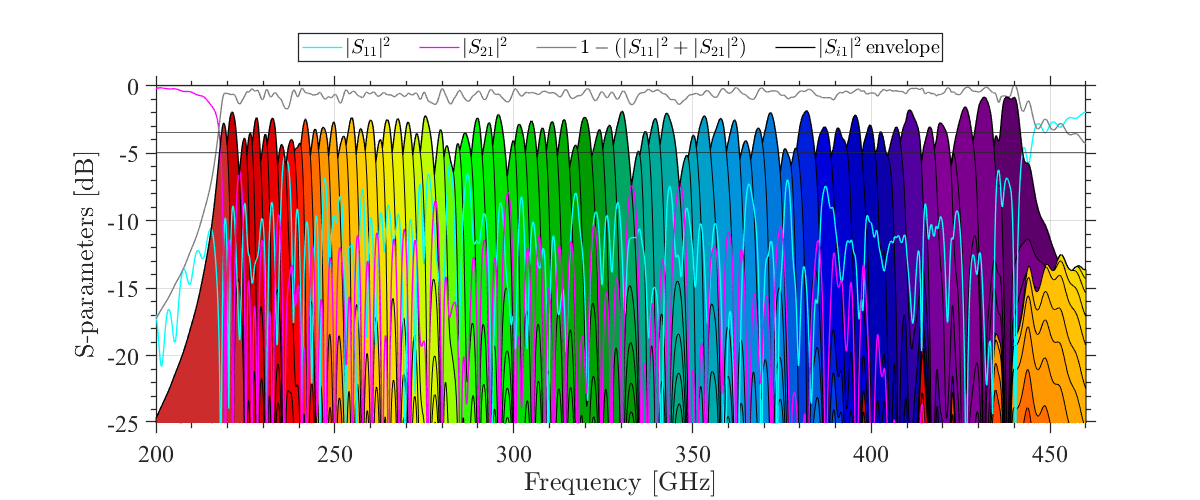

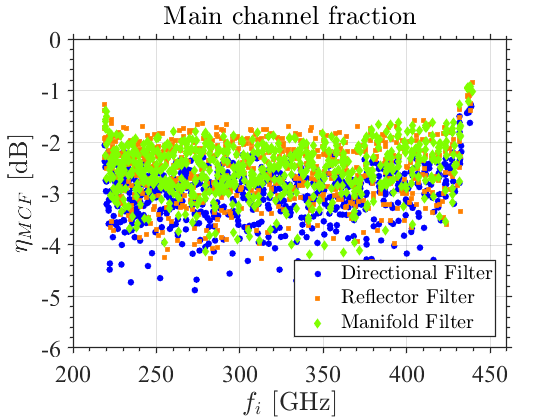

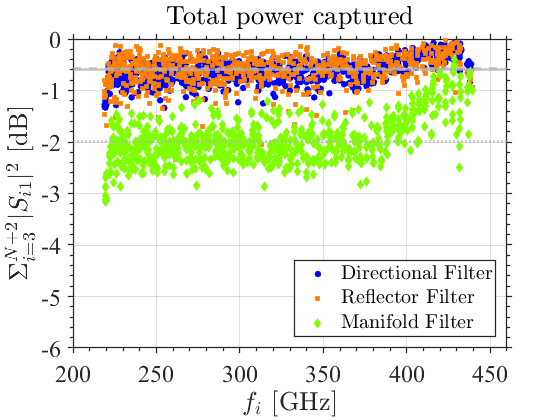

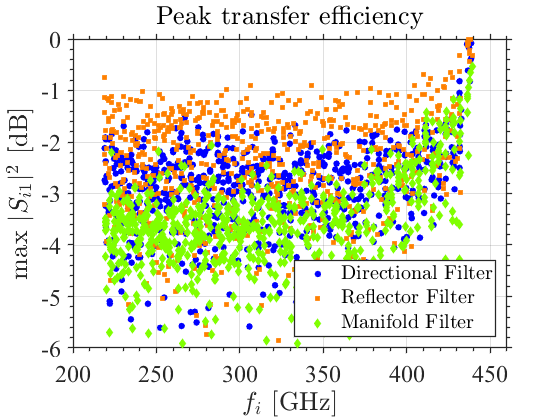

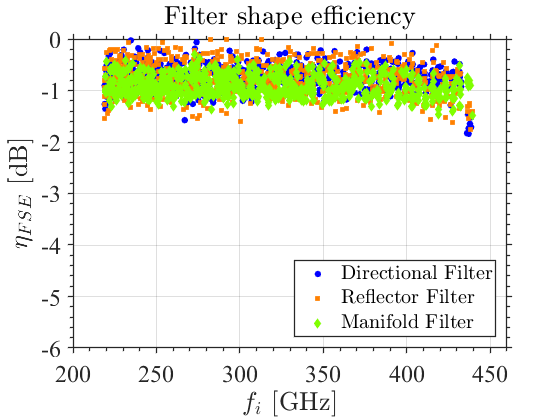

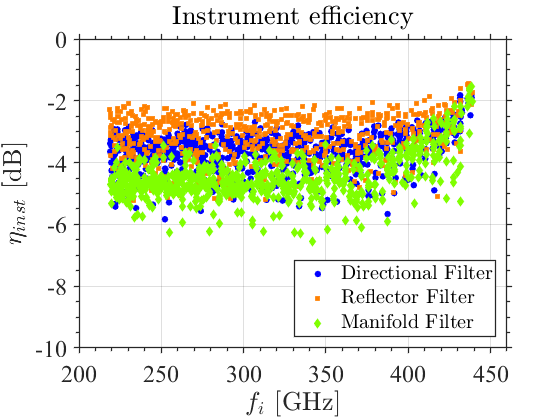

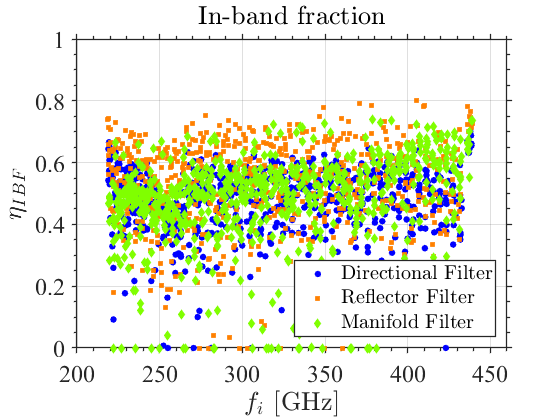

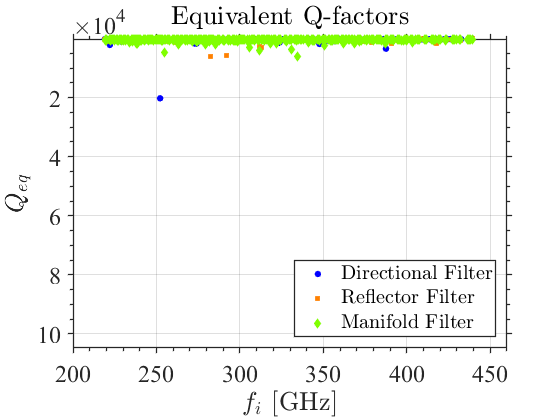



formatPlotting();